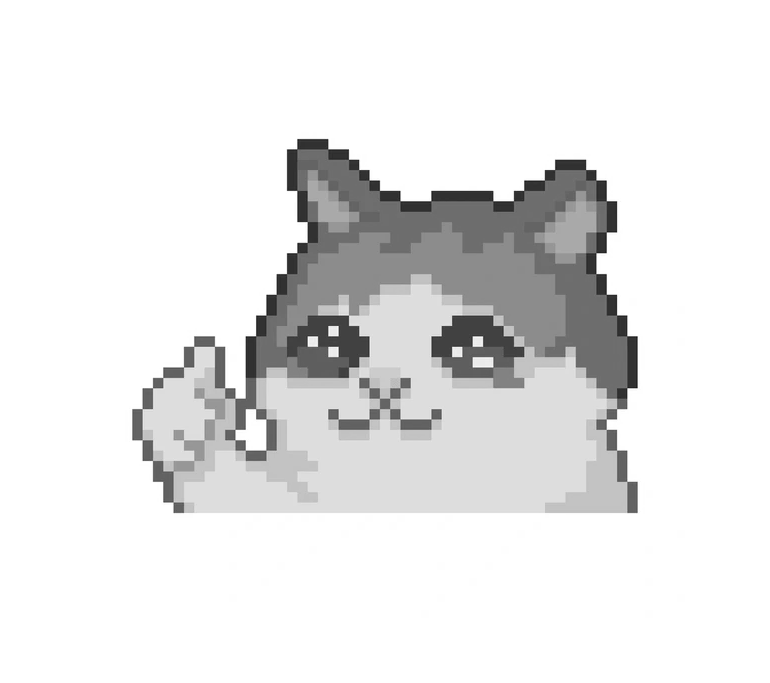

image = imread('task_3.png');

image = im2gray(image);
image = double(image) / 255;

imshow(image);

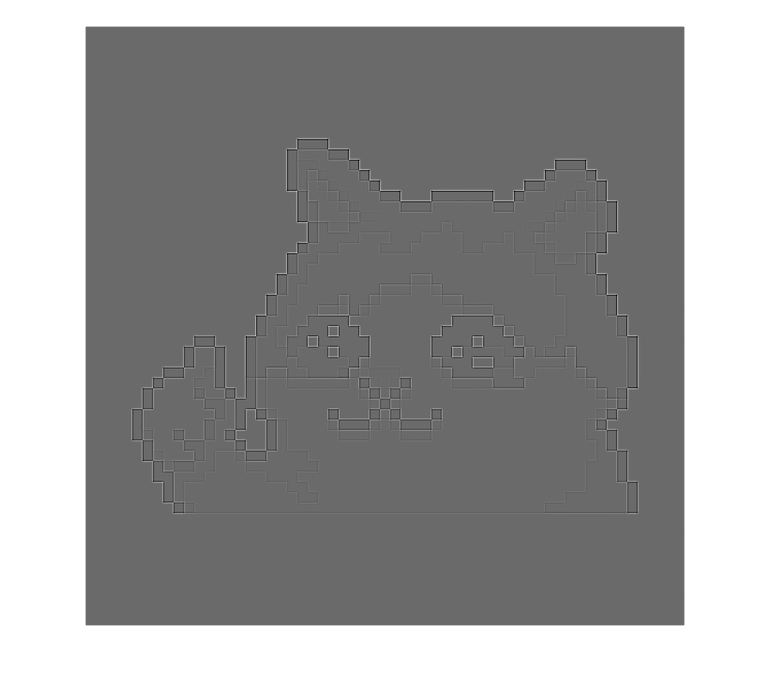

K = [
     -1, -1, -1;
     -1,  8, -1;
     -1, -1, -1
];

image_conv = conv2(image, K, 'same');

image_conv = normalize_image(image_conv);

imshow(image_conv);

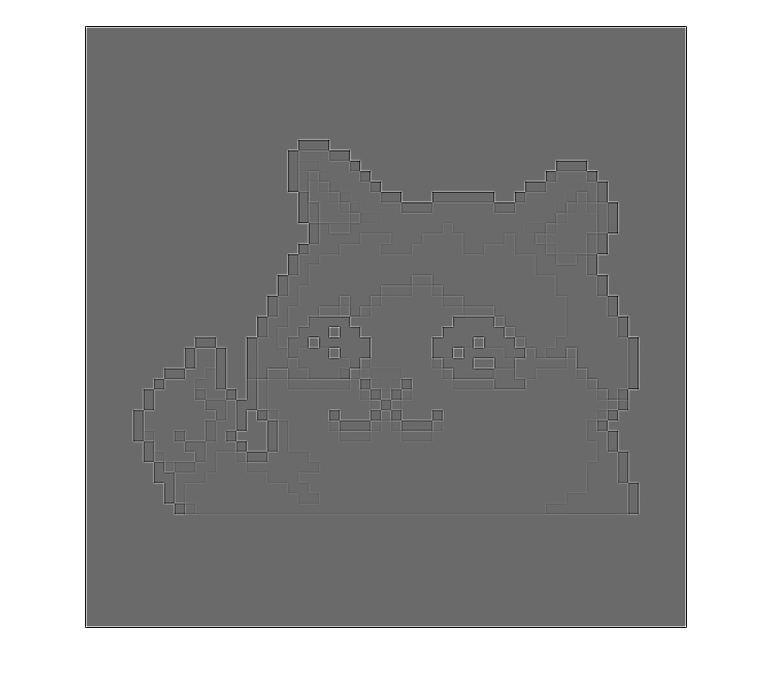

[image_height, image_width] = size(image);
[kernel_height, kernel_width] = size(K);

image_fourier = fftshift(fft2( ...
    image, ...
    image_height + kernel_height - 1, image_width + kernel_width - 1));

kernel_fourier = fftshift(fft2( ...
    K, ...
    image_height + kernel_height - 1, image_width + kernel_width - 1));

image_fourier = image_fourier .* kernel_fourier;

image_filtered = ifft2(fftshift(image_fourier));

image_filtered = normalize_image(image_filtered);

imshow(image_filtered);

function image = normalize_image(image)
    min_val = min(image(:));
    range = max(image(:)) - min_val;

    image = (image - min_val) / range;
end